# **Cooperative Localization**

Importing Measured Data

clear;
given_data = importdata("cooplocalization_finalproj_KFdata.mat");

Q_true = given_data.Qtrue;
R_true = given_data.Rtrue;
state_labels = given_data.measLabels;
y_measured = given_data.ydata;
time_series = given_data.tvec;
y_measured(isnan(y_measured)) = 0;

dT = 0.1;                                           % delta T for discretization

### **Ground Vehicle**

Parameters

L = 0.5;                                            % m
vel_UGV_max = 3;                                    % ms^-1
steering_angle_range = [-5*pi/12, 5*pi/12];         % rad

Nominal Parameters

v_g0 = 2;                                           % ms^-1
east_g0 = 10;                                       % m
north_g0 = 0;                                       % m
heading_g0 = pi/2;                                  % rad (defined as 'theta_g' in equations)
steering_g0 = -pi/18;                               % rad

### **Aerial Vehicle**

Parameters

vel_UAV_range = [10, 20];                           % ms^-1
steering_vel_range = [-pi/6, pi/6];                 % rads^-1

#### Nominal Parameters

v_a0 = 12;                                          % ms^-1
east_a0 = -60;                                      % m
north_a0 = 0;                                       % m
heading_a0 = -pi/2;                                 % rad (defined as 'theta_a' in equations)
steering_vel_a0 = pi/25;                            % rads^-1

### **Linearized System Dynamics**

Definition of matricies, delA, delB

x_nom = [east_g0; north_g0; heading_g0; east_a0; north_a0; heading_a0];
x0 = [0; 1; 0; 0; 0; 0.1];
u_nom = [v_g0; steering_g0; v_a0; steering_vel_a0];


[F, G] = compute_linearized_matrices(x_nom, u_nom, L, dT);

**Non-Linear Dynamics Simulation**

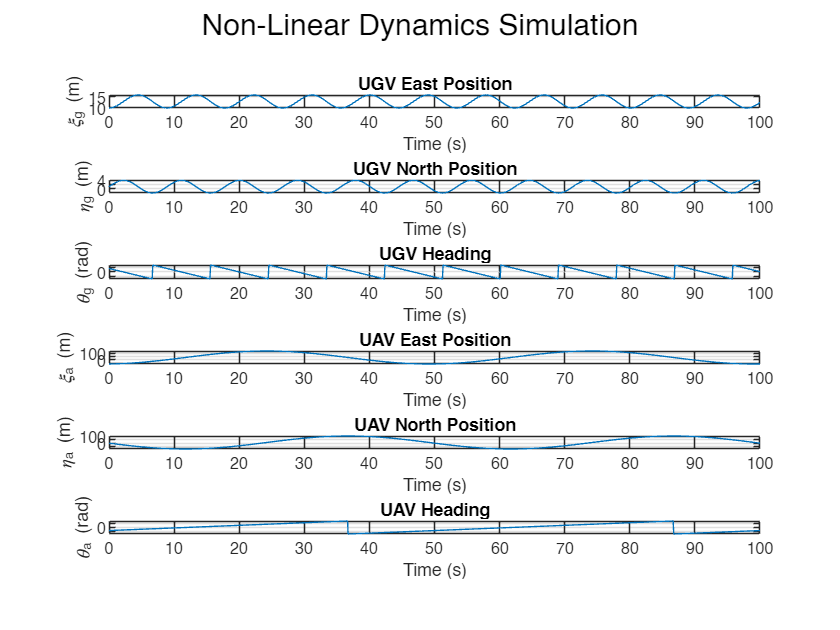

t_span = [0 100];    
t_eval = 0:dT:100;

perturb_x0 = [0;    
              1;    
              0;    
              0;    
              0;    
              0.1];

x0_nl = [east_g0;
      north_g0;   
      heading_g0; 
      east_a0;    
      north_a0
      heading_a0] + perturb_x0;

u = [v_g0;            
     steering_g0;     
     v_a0;           
     steering_vel_a0];

options = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);
dynamics_handle = @(t,x) system_dynamics(t, x, u, L);

[t, x] = ode45(dynamics_handle, t_span, x0_nl, options);

y = zeros(length(t), 5);
for i = 1:length(t)
    y(i,:) = measurement_model(x(i,:)');
end

% Plotting
figure;
subplot(6,1,1);
plot(t, x(:,1)); grid on;
title('UGV East Position'); xlabel('Time (s)'); ylabel('\xi_g (m)');

subplot(6,1,2);
plot(t, x(:,2)); grid on;
title('UGV North Position'); xlabel('Time (s)'); ylabel('\eta_g (m)');

subplot(6,1,3);
plot(t, wrapToPi(x(:,3))); grid on;
title('UGV Heading'); xlabel('Time (s)'); ylabel('\theta_g (rad)');

subplot(6,1,4);
plot(t, x(:,4)); grid on;
title('UAV East Position'); xlabel('Time (s)'); ylabel('\xi_a (m)');

subplot(6,1,5);
plot(t, x(:,5)); grid on;
title('UAV North Position'); xlabel('Time (s)'); ylabel('\eta_a (m)');

subplot(6,1,6);
plot(t, wrapToPi(x(:,6))); grid on;
title('UAV Heading'); xlabel('Time (s)'); ylabel('\theta_a (rad)');

sgtitle('Non-Linear Dynamics Simulation')

**Linearized Dynamics Simulation**

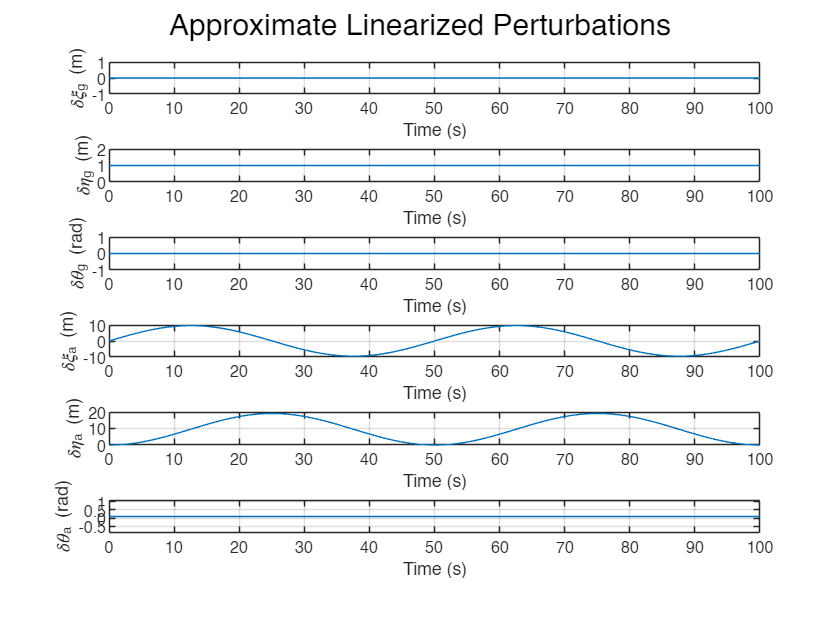

[dx_hist, x_nom_hist] = simulate_linearized_system(x0, x_nom, u_nom, L, dT, 100);

figure;

subplot(6, 1, 1);
plot(time_series, dx_hist(1, :));
grid on;
xlabel('Time (s)'); ylabel('\delta\xi_g (m)');

subplot(6, 1, 2);
plot(time_series, dx_hist(2, :))
grid on;
xlabel('Time (s)'); ylabel('\delta\eta_g (m)');

subplot(6, 1, 3);
plot(time_series, dx_hist(3, :))
grid on;
xlabel('Time (s)'); ylabel('\delta\theta_g (rad)');

subplot(6, 1, 4);
plot(time_series, dx_hist(4, :))
grid on;
xlabel('Time (s)'); ylabel('\delta\xi_a (m)');

subplot(6, 1, 5);
plot(time_series, dx_hist(5, :))
grid on;
xlabel('Time (s)'); ylabel('\delta\eta_a (m)');

subplot(6, 1, 6);
plot(time_series, dx_hist(6, :))
grid on;
xlabel('Time (s)'); ylabel('\delta\theta_a (rad)');

sgtitle('Approximate Linearized Perturbations');

#### Monte Carlo simulation

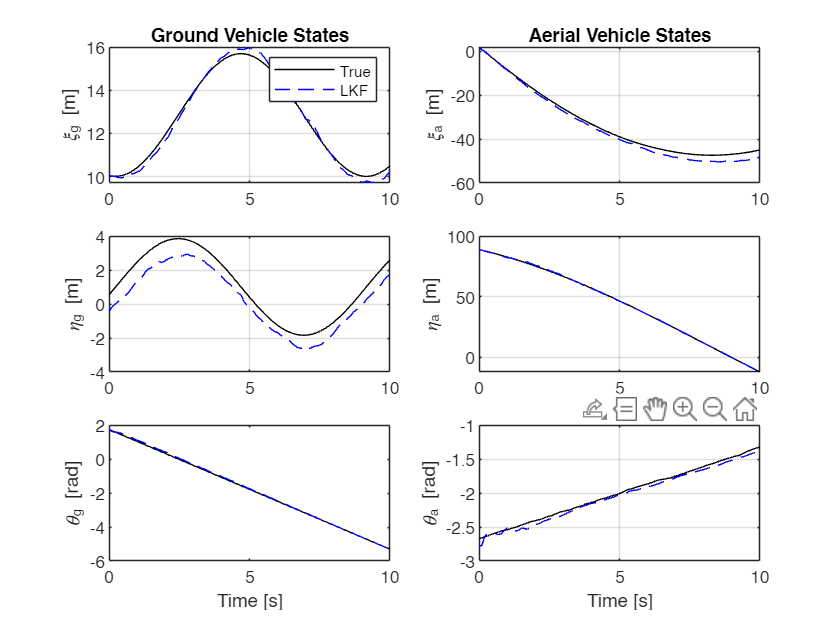

% Tuning parameters
Q_scale = diag([0.7485, 0.09, 0.1, 1.8, 0.05, 1])*.04;
R_scale = diag([0.776, 1.762, 1, 1.22, 0.5]);

% Monte Carlo simulation parameters
Nsims = 50;                  % Number of Monte Carlo runs
T = 10;                      % Simulation time
steps = T/dT + 1;
time = 0:dT:T;
n = 6;                      % State dimension
p = 5;                      % Measurement dimension

% Storage for NEES and NIS
NEESsamps = zeros(Nsims, steps-1);
NISsamps = zeros(Nsims, steps-1);

for sim = 1:Nsims
    % Initialize state storage
    x_true = zeros(6, steps);
    x_est = zeros(6, steps);
    P = zeros(6, 6, steps);
    
    % Initialize states and covariance
    x_true(:,1) = x_nom + perturb_x0;    
    x_est(:,1) = x_nom;    
    P(:,:,1) = diag([1^2, 1^2, (pi/8)^2, 1^2, 1^2, (pi/8)^2]);
    
    x_nom_k = x_nom;
    
    for k = 1:steps-1
        % Simulate true state
        [~, x_temp] = ode45(@(t,x) system_dynamics(t, x, u_nom, L), [0 dT], x_true(:,k));
        x_true(:,k+1) = x_temp(end,:)' + mvnrnd(zeros(1,6), Q_scale * Q_true * Q_scale')';
        
        % Generate measurement with scaled noise
        y = measurement_model(x_true(:,k+1)) + mvnrnd(zeros(1,5), R_scale * R_true * R_scale')';
        
        % LKF Prediction Step
        [F, G] = compute_linearized_matrices(x_nom, u_nom, L, dT);
        x_nom_next = update_nominal_state(x_nom, u_nom, dT);
        dx_pred = F * (x_est(:,k) - x_nom);
        P_pred = F * P(:,:,k) * F' + Q_scale * Q_true * Q_scale';
        x_pred = x_nom_next + dx_pred;
        
        % LKF Update Step
        H = measurement_jacobian(x_nom_next);
        y_nom = measurement_model(x_nom_next);
        y_pred = measurement_model(x_pred);
        
        innov = y - y_pred;
        innov([1,3]) = wrapToPi(innov([1,3]));  % Wrap angle innovations
        
        S = H * P_pred * H' + R_scale * R_true * R_scale';
        K = P_pred * H' / S;
        
        dx_update = dx_pred + K * innov;
        x_est(:,k+1) = x_nom_next + dx_update;
        P(:,:,k+1) = (eye(6) - K*H) * P_pred;
        
        % Update nominal state for next step
        x_nom = x_nom_next;
        
        % Compute NEES
        err = x_true(:,k) - x_est(:,k);
        err([3,6]) = wrapToPi(err([3,6]));  % Wrap angle errors
        NEESsamps(sim,k) = err' / P(:,:,k) * err;
        
        % Compute NIS
        NISsamps(sim,k) = innov' / S * innov;
    end
end

% Plotting results
figure('Name', 'State Estimation Results');

% UGV States
subplot(3,2,1)
plot(time, x_true(1,:), 'k', time, x_est(1,:), 'b--')
grid on
ylabel('\xi_g [m]')
title('Ground Vehicle States')
legend('True', 'LKF')

subplot(3,2,3)
grid on
plot(time, x_true(2,:), 'k', time, x_est(2,:), 'b--')
grid on
ylabel('\eta_g [m]')

subplot(3,2,5)
grid on
theta_g_true = unwrap(x_true(3,:));                     % Unwrap true trajectory
theta_g_est = unwrap(x_est(3,:));                       % Unwrap estimated trajectory
plot(time, theta_g_true, 'k', time, theta_g_est, 'b--')
ylabel('\theta_g [rad]')
xlabel('Time [s]')

% UAV States
subplot(3,2,2)
plot(time, x_true(4,:), 'k', time, x_est(4,:), 'b--')
grid on
ylabel('\xi_a [m]')
title('Aerial Vehicle States')

subplot(3,2,4)
plot(time, x_true(5,:), 'k', time, x_est(5,:), 'b--')
grid on
ylabel('\eta_a [m]')

subplot(3,2,6)
plot(time, x_true(6,:), 'k', time, x_est(6,:), 'b--')
grid on
ylabel('\theta_a [rad]')
xlabel('Time [s]')

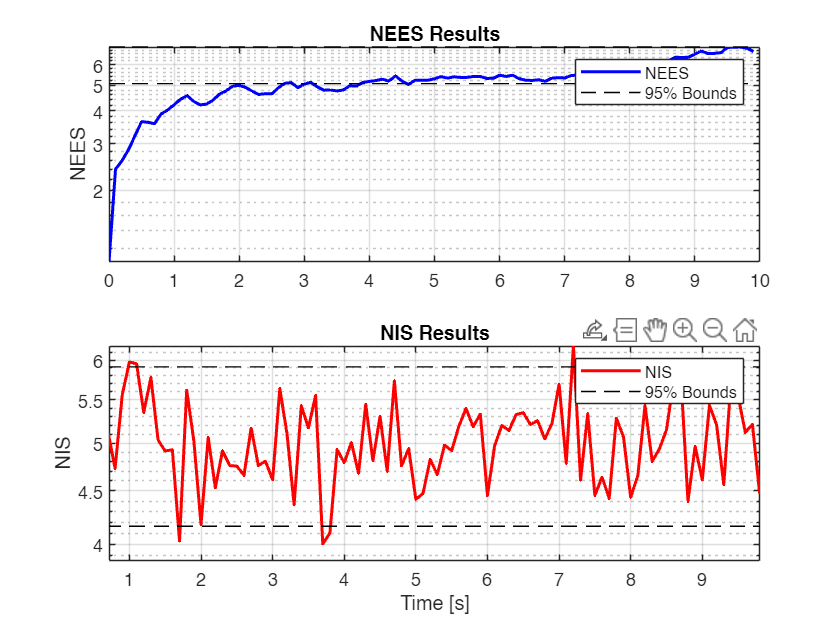


% Compute chi-square test bounds (95% confidence)
alpha = 0.05;
r1_nees = chi2inv(alpha/2, n*Nsims)/(Nsims);
r2_nees = chi2inv(1-alpha/2, n*Nsims)/(Nsims);
r1_nis = chi2inv(alpha/2, p*Nsims)/(Nsims);
r2_nis = chi2inv(1-alpha/2, p*Nsims)/(Nsims);

% Calculate means
mean_NEES = mean(NEESsamps, 1);
mean_NIS = mean(NISsamps, 1);

% Plot NEES and NIS results
figure;
subplot(2,1,1);
semilogy(time(1:end-1), mean_NEES, 'b-', 'LineWidth', 1.5);
hold on;
plot(time(1:end-1), r1_nees*ones(size(time(1:end-1))), 'k--');
plot(time(1:end-1), r2_nees*ones(size(time(1:end-1))), 'k--');
ylabel('NEES');
title('NEES Results');
legend('NEES', '95% Bounds');
grid on;

subplot(2,1,2);
semilogy(time(1:end-1), mean_NIS, 'r-', 'LineWidth', 1.5);
hold on;
plot(time(1:end-1), r1_nis*ones(size(time(1:end-1))), 'k--');
plot(time(1:end-1), r2_nis*ones(size(time(1:end-1))), 'k--');
ylabel('NIS');
xlabel('Time [s]');
title('NIS Results');
legend('NIS', '95% Bounds');
grid on;

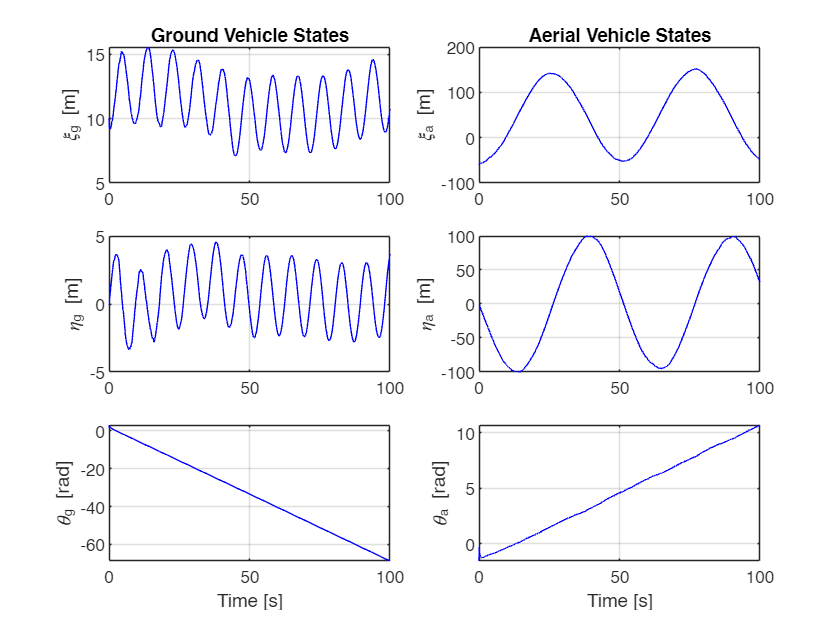

x_nom = [10; 0; pi/2; -60; 0; -pi/2];                       % Initial nominal state
u_nom = [v_g0; steering_g0; v_a0; steering_vel_a0];         % Control inputs

% Storage
n_steps = length(time_series);
x_est = zeros(6, n_steps);
P = zeros(6, 6, n_steps);

% Initial conditions
x_est(:,1) = x_nom;
P(:,:,1) = diag([1^2, 1^2, (pi/8)^2, 1^2, 1^2, (pi/8)^2]);
x_nom_k = x_nom;

% Main filter loop
for k = 1:n_steps-1
    % LKF Prediction Step
    [F, G] = compute_linearized_matrices(x_nom_k, u_nom, L, dT);
    x_nom_next = update_nominal_state(x_nom_k, u_nom, dT);
    
    dx_pred = F * (x_est(:,k) - x_nom_k);
    P_pred = F * P(:,:,k) * F' + Q_scale * Q_true * Q_scale';
    x_pred = x_nom_next + dx_pred;
    
    % LKF Update Step
    H = measurement_jacobian(x_nom_next);
    y_nom = measurement_model(x_nom_next);
    y_pred = measurement_model(x_pred);
    
    % Use actual measurements from data
    y = y_measured(:,k);
    
    innov = y - y_pred;
    innov([1,3]) = wrapToPi(innov([1,3]));
    
    S = H * P_pred * H' + R_scale * R_true * R_scale';
    K = P_pred * H' / S;
    
    dx_update = dx_pred + K * innov;
    x_est(:,k+1) = x_nom_next + dx_update;
    P(:,:,k+1) = (eye(6) - K*H) * P_pred;
    
    % Update nominal state
    x_nom_k = x_nom_next;
end

% Plot results
figure('Name', 'LKF State Estimation with Real Data');

% UGV States
subplot(3,2,1)
plot(time_series, x_est(1,:), 'b-')
ylabel('\xi_g [m]')
title('Ground Vehicle States')
grid on

subplot(3,2,3)
plot(time_series, x_est(2,:), 'b-')
ylabel('\eta_g [m]')
grid on

subplot(3,2,5)
plot(time_series, unwrap(x_est(3,:)), 'b-')
ylabel('\theta_g [rad]')
xlabel('Time [s]')
grid on

% UAV States
subplot(3,2,2)
plot(time_series, x_est(4,:), 'b-')
ylabel('\xi_a [m]')
title('Aerial Vehicle States')
grid on

subplot(3,2,4)
plot(time_series, x_est(5,:), 'b-')
ylabel('\eta_a [m]')
grid on

subplot(3,2,6)
plot(time_series, unwrap(x_est(6,:)), 'b-')
ylabel('\theta_a [rad]')
xlabel('Time [s]')
grid on

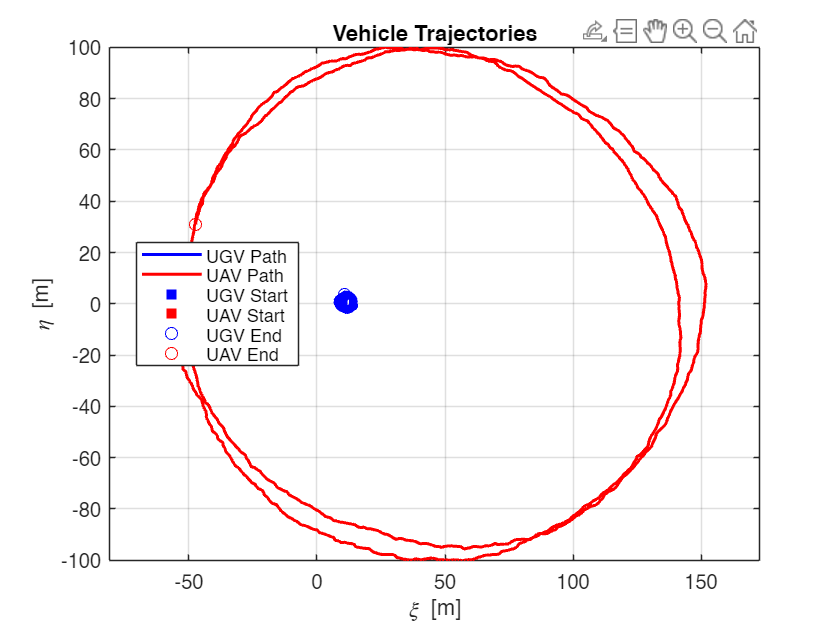


% Plot 2D trajectories
figure('Name', 'Vehicle Trajectories');
plot(x_est(1,:), x_est(2,:), 'b-', 'LineWidth', 1.5, 'DisplayName', 'UGV Path');
hold on;
plot(x_est(4,:), x_est(5,:), 'r-', 'LineWidth', 1.5, 'DisplayName', 'UAV Path');
plot(x_est(1,1), x_est(2,1), 'bs', 'MarkerFaceColor', 'b', 'DisplayName', 'UGV Start');
plot(x_est(4,1), x_est(5,1), 'rs', 'MarkerFaceColor', 'r', 'DisplayName', 'UAV Start');
plot(x_est(1,end), x_est(2,end), 'bo', 'DisplayName', 'UGV End');
plot(x_est(4,end), x_est(5,end), 'ro', 'DisplayName', 'UAV End');
xlabel('\xi [m]'); ylabel('\eta [m]');
title('Vehicle Trajectories');
legend('Location', 'best');
grid on;
axis equal;

function dx = system_dynamics(t, x, u, L)

    x(3) = wrapToPi(x(3));  % UGV heading
    x(6) = wrapToPi(x(6));  % UAV heading

    theta_g = x(3);
    theta_a = x(6);

    v_g = u(1);
    phi_g = u(2);
    v_a = u(3);
    omega_a = u(4);

    dx = zeros(6,1);
    
    % UGV dynamics
    dx(1) = v_g * cos(theta_g);        % ξ̇g
    dx(2) = v_g * sin(theta_g);        % η̇g
    dx(3) = (v_g/L) * tan(phi_g);      % θ̇g
    
    % UAV dynamics
    dx(4) = v_a * cos(theta_a);        % ξ̇a
    dx(5) = v_a * sin(theta_a);        % η̇a
    dx(6) = omega_a;                   % θ̇a
end

function y = measurement_model(x)

    xi_g = x(1); eta_g = x(2); theta_g = wrapToPi(x(3));
    xi_a = x(4); eta_a = x(5); theta_a = wrapToPi(x(6));

    delta_x = xi_a - xi_g;
    delta_y = eta_a - eta_g;

    bearing_g2a = wrapToPi(atan2(delta_y, delta_x) - theta_g);

    range = sqrt(delta_x^2 + delta_y^2);

    bearing_a2g = wrapToPi(atan2(-delta_y, -delta_x) - theta_a);

    y = [bearing_g2a;
         range;
         bearing_a2g;
         xi_a;
         eta_a];
end

% Compute linearized dynamics matrices
function [F, G] = compute_linearized_matrices(x_nom, u_nom, L, dT)
    % Extract nominal states and inputs
    theta_g = x_nom(3);
    theta_a = x_nom(6);
    v_g = u_nom(1);
    phi_g = u_nom(2);
    v_a = u_nom(3);
    
    % Initialize continuous-time matrices
    delA = zeros(6, 6);
    delB = zeros(6, 4);
    
    % Fill delA matrix - only include terms that actually appear in partial derivatives
    % UGV dynamics
    delA(1,3) = -v_g * sin(theta_g);  % ∂ẋg/∂θg
    delA(2,3) = v_g * cos(theta_g);   % ∂ẏg/∂θg
    
    % UAV dynamics
    delA(4,6) = -v_a * sin(theta_a);  % ∂ẋa/∂θa
    delA(5,6) = v_a * cos(theta_a);   % ∂ẏa/∂θa
    
    % Fill delB matrix
    % UGV input mapping
    delB(1,1) = cos(theta_g);         % ∂ẋg/∂v_g
    delB(2,1) = sin(theta_g);         % ∂ẏg/∂v_g
    delB(3,1) = tan(phi_g)/L;         % ∂θ̇g/∂v_g
    delB(3,2) = v_g/(L * cos(phi_g)^2);  % ∂θ̇g/∂φ_g
    
    % UAV input mapping
    delB(4,3) = cos(theta_a);         % ∂ẋa/∂v_a
    delB(5,3) = sin(theta_a);         % ∂ẏa/∂v_a
    delB(6,4) = 1;                    % ∂θ̇a/∂ω_a
    
    % Construct the complete state-space matrix for discretization
    M = [delA, delB; 
         zeros(4, 6), zeros(4, 4)];
    
    % Compute matrix exponential for exact discretization
    expM = expm(M*dT);
    
    % Extract discrete-time matrices
    F = expM(1:6, 1:6);
    G = expM(1:6, 7:10);
    
    % Verify stability (for debugging)
    eigs = abs(eig(F));
    if any(eigs > 1.001)  % Allow small numerical errors
        warning('System is unstable! Max eigenvalue magnitude: %f', max(eigs));
    end
end

function [dx_hist, x_nom_hist] = simulate_linearized_system(x0, x_nom, u_nom, L, dT, T_final)
    N = floor(T_final/dT) + 1;
    dx_hist = zeros(6, N);
    x_nom_hist = zeros(6, N);
    
    % Initial conditions
    dx_hist(:,1) = x0;  % Initial perturbation
    x_nom_hist(:,1) = x_nom;  % Initial nominal state

    for k = 1:N-1
        [F, ~] = compute_linearized_matrices(x_nom_hist(:,k), u_nom, L, dT);
        
        dx_hist(:,k+1) = F * dx_hist(:,k);
        x_nom_hist(:,k+1) = update_nominal_state(x_nom_hist(:,k), u_nom, dT);
    end
end

function x_next = update_nominal_state(x, u, dT)
    dx = zeros(6,1);
    theta_g = x(3);
    theta_a = x(6);
    v_g = u(1);
    phi_g = u(2);
    v_a = u(3);
    omega_a = u(4);
    
    dx(1) = v_g * cos(theta_g);
    dx(2) = v_g * sin(theta_g);
    dx(3) = (v_g/0.5) * tan(phi_g);
    dx(4) = v_a * cos(theta_a);
    dx(5) = v_a * sin(theta_a);
    dx(6) = omega_a;

    x_next = x + dx * dT;
    
    % Wrap angles to [-pi, pi]
    x_next(3) = wrapToPi(x_next(3));
    x_next(6) = wrapToPi(x_next(6));
end

function H = measurement_jacobian(x)
    % Extract states using your notation
    east_g0 = x(1);
    north_g0 = x(2);
    east_a0 = x(4);
    north_a0 = x(5);
    
    % Initialize H matrix
    H = zeros(5, 6);
    
    % Your derived H matrix
    H(1, 1) = (north_a0 - north_g0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(1, 2) = -(east_a0 - east_g0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(1, 3) = -1;
    H(1, 4) = -(north_a0 - north_g0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(1, 5) = (east_a0 - east_g0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(1, 6) = 0;
    
    H(2, 1) = (east_g0 - east_a0)/sqrt((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(2, 2) = (north_g0 - north_a0)/sqrt((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(2, 3) = 0;
    H(2, 4) = -(east_g0 - east_a0)/sqrt((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(2, 5) = -(north_g0 - north_a0)/sqrt((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(2, 6) = 0;
    
    H(3, 1) = -(north_g0 - north_a0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(3, 2) = (east_g0 - east_a0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(3, 3) = 0;
    H(3, 4) = (north_g0 - north_a0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(3, 5) = -(east_g0 - east_a0)/((east_a0 - east_g0)^2 + (north_a0 - north_g0)^2);
    H(3, 6) = -1;
    
    H(4, 4) = 1;
    H(5, 5) = 1;
end